% Definiowanie stałej C1
C1 = 0.75; % przykładowa wartość, zmień ją zgodnie z zadaniem
C2 = 0.55;

alfa1 = 13;
alfa2 = 12;
tau = 120;

% Definiowanie funkcji F1(t), FD(t), i F2(h1)
F1_in = @(t)73;
F1 = @(t) F1_in(t - tau);     % przykład funkcji dopływu zależnej od czasu
FD = @(t) 15;               % przykład stałego dodatkowego dopływu
F2 = @(h1) alfa1 * h1^0.5;
F3 = @(h2) alfa2 * h2^0.5;

% Definiowanie równania różniczkowego jako funkcji anonimowej
odefun = @(t, y) [
    (F1(t) + FD(t) - F2(y(1))) / (2 * C1 * y(1));    % równanie dla dh1/dt
    (F2(y(1)) - F3(y(2))) / (2 * C2 * y(2))          % równanie dla dh2/dt
];


% Ustalanie początkowych warunków i zakresu czasu
h1_0 = 1;            % początkowa wartość h1
h2_0 = 1;            % początkowa wartość h2
tspan = [0, 10000];     % zakres czasu

% Rozwiązywanie układu równań za pomocą ode45
[t, y] = ode15s(odefun, tspan, [h1_0, h2_0]);

% Wykres wyników
figure;
plot(t, y(:, 1), 'b', 'DisplayName', 'h1(t)'); % wykres dla h1
hold on;
plot(t, y(:, 2), 'r', 'DisplayName', 'h2(t)'); % wykres dla h2
xlabel('Czas t');
ylabel('Wysokości h1(t) i h2(t)');
title('Rozwiązanie układu równań różniczkowych dla h1(t) i h2(t)');
legend;
grid on;
hold off;

xlim([0 10000]);
ylim([0.0 60.0]);
 
h1t = findobj(gcf, "DisplayName", "h1(t)");

h1t =   Line (h1(t)) with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 6.8642e-04 0.0014 0.0021 0.0043 0.0065 0.0088 0.0110 0.0156 0.0202 0.0248 0.0293 0.0339 0.0434 0.0529 0.0624 0.0718 0.0813 0.1007 0.1202 0.1396 0.1591 0.1785 0.2198 0.2611 0.3024 0.3437 0.3851 0.4640 0.5429 … ] (1×103 double)
              YData: [1 1.0333 1.0655 1.0968 1.1934 1.2822 1.3648 1.4421 1.5869 1.7183 1.8395 1.9524 2.0585 2.2598 2.4425 2.6110 2.7678 2.9148 3.1917 3.4431 3.6749 3.8905 4.0924 4.4848 4.8403 5.1683 5.4731 5.7566 6.2489 6.6916 7.1013 … ] (1×103 double)

  Show all pr

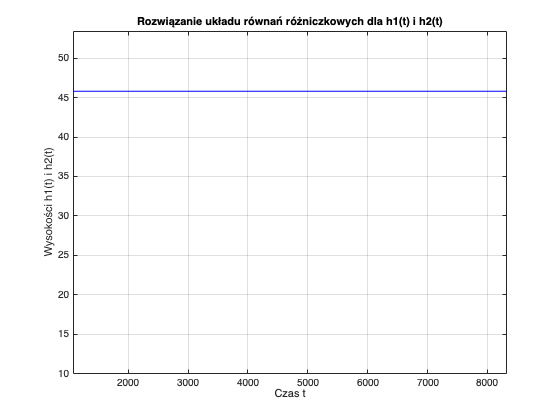

datatip(h1t,925.1,45.82);

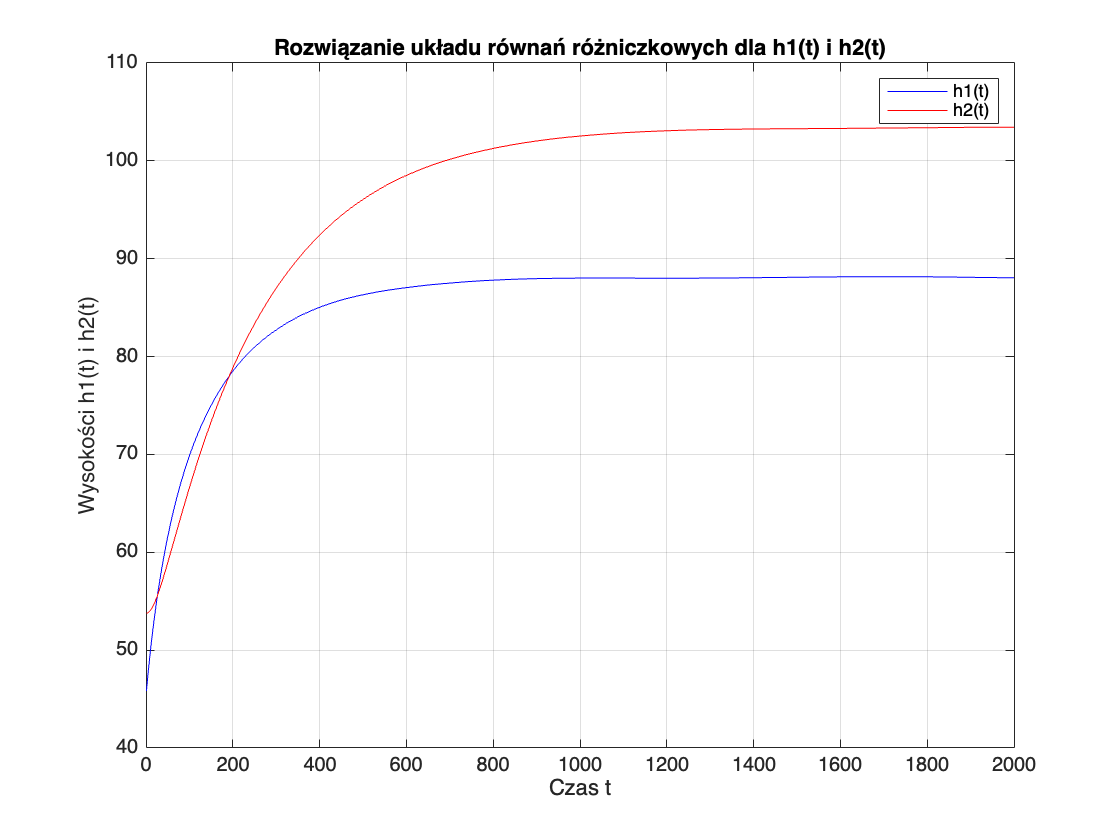


t_span = [1:2000];
F1_in = @(t)100;
tau = 120;
F1 = @(t) F1_in(t - tau);     % przykład funkcji dopływu zależnej od czasu
FD = @(t) 22;
h1_0 = 45.8225;            
h2_0 = 53.7778; 


[t, h] = zbiornik(t_span, h1_0, h2_0, F1, FD);

figure;
plot(t, h(:, 1), 'b', 'DisplayName', 'h1(t)'); % wykres dla h1
hold on;
plot(t, h(:, 2), 'r', 'DisplayName', 'h2(t)'); % wykres dla h2
xlabel('Czas t');
ylabel('Wysokości h1(t) i h2(t)');
title('Rozwiązanie układu równań różniczkowych dla h1(t) i h2(t)');
legend;
grid on;
hold off;

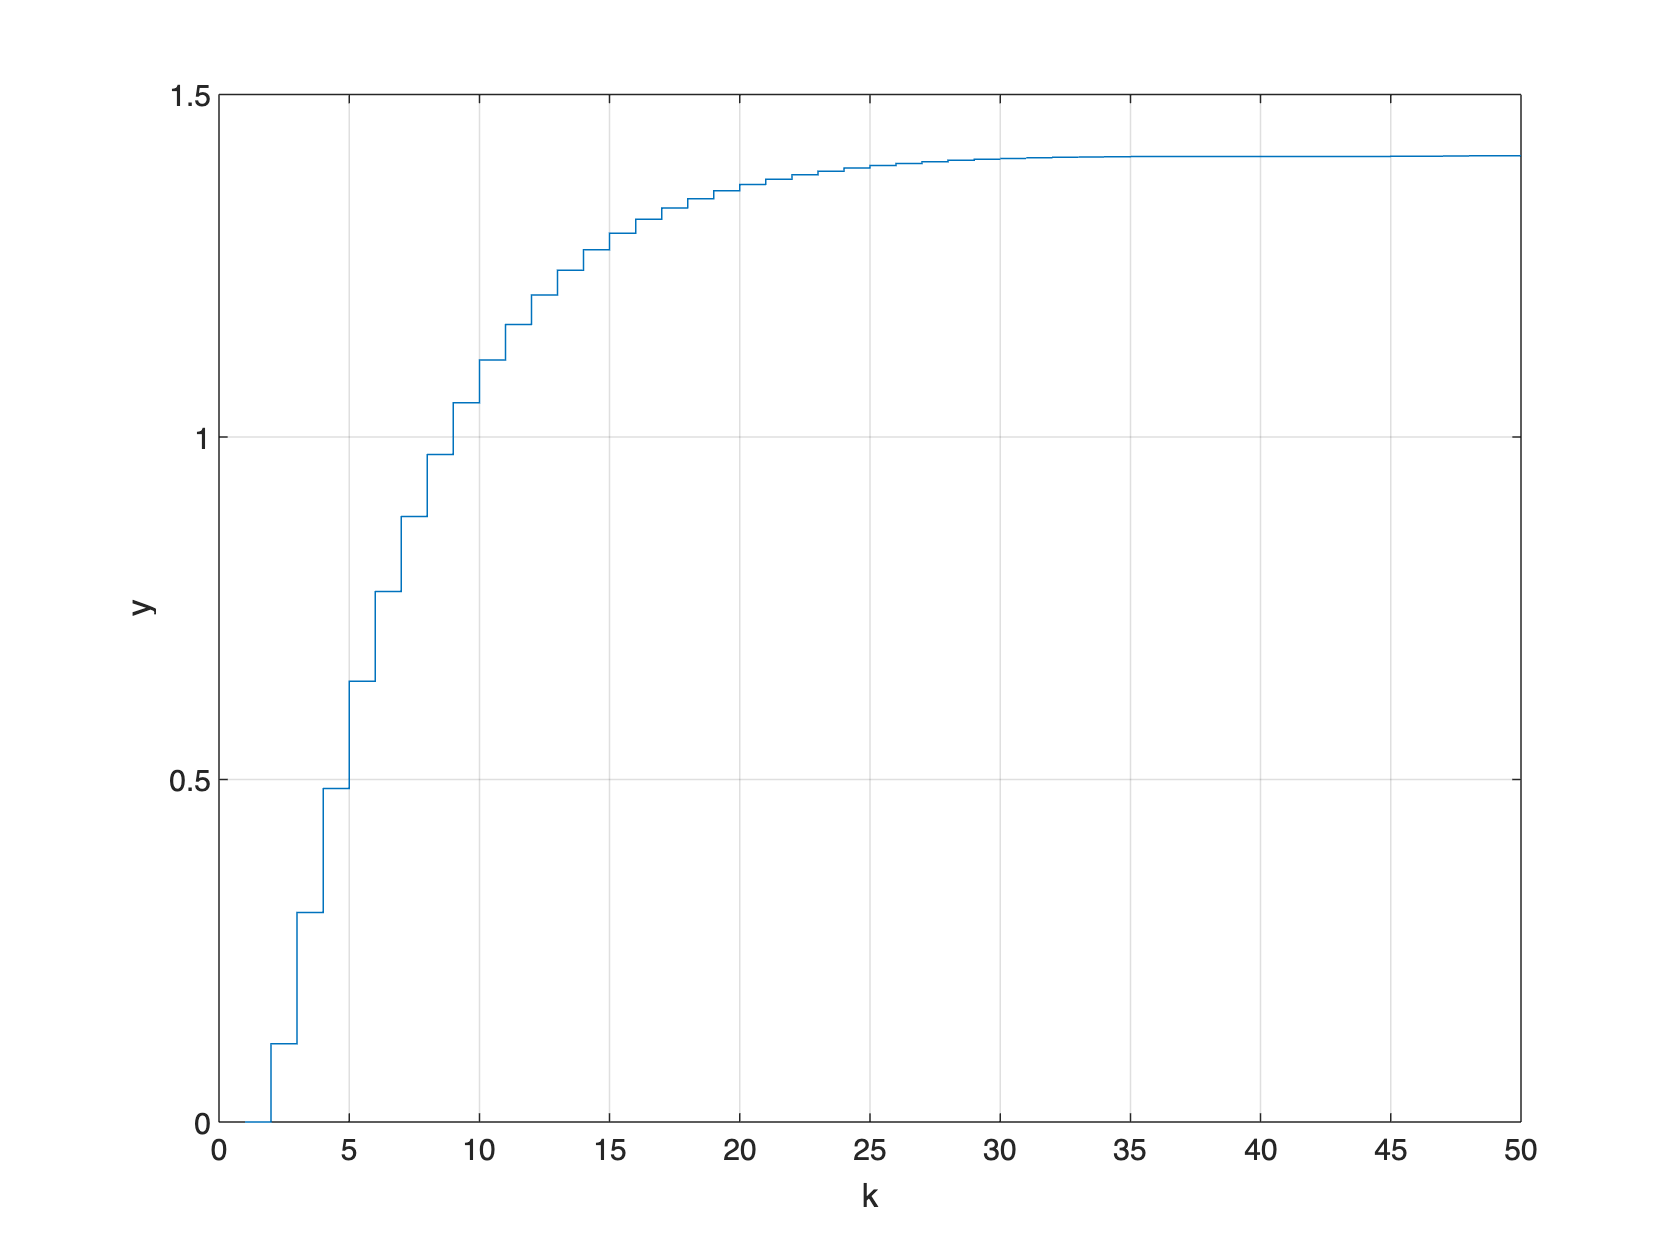

clear;
t_step  = 2000;
Ts = 40;
s = get_s(t_step, Ts);
figure;
stairs(1:length(s), s);
xlabel('k');
ylabel('y');
grid on;

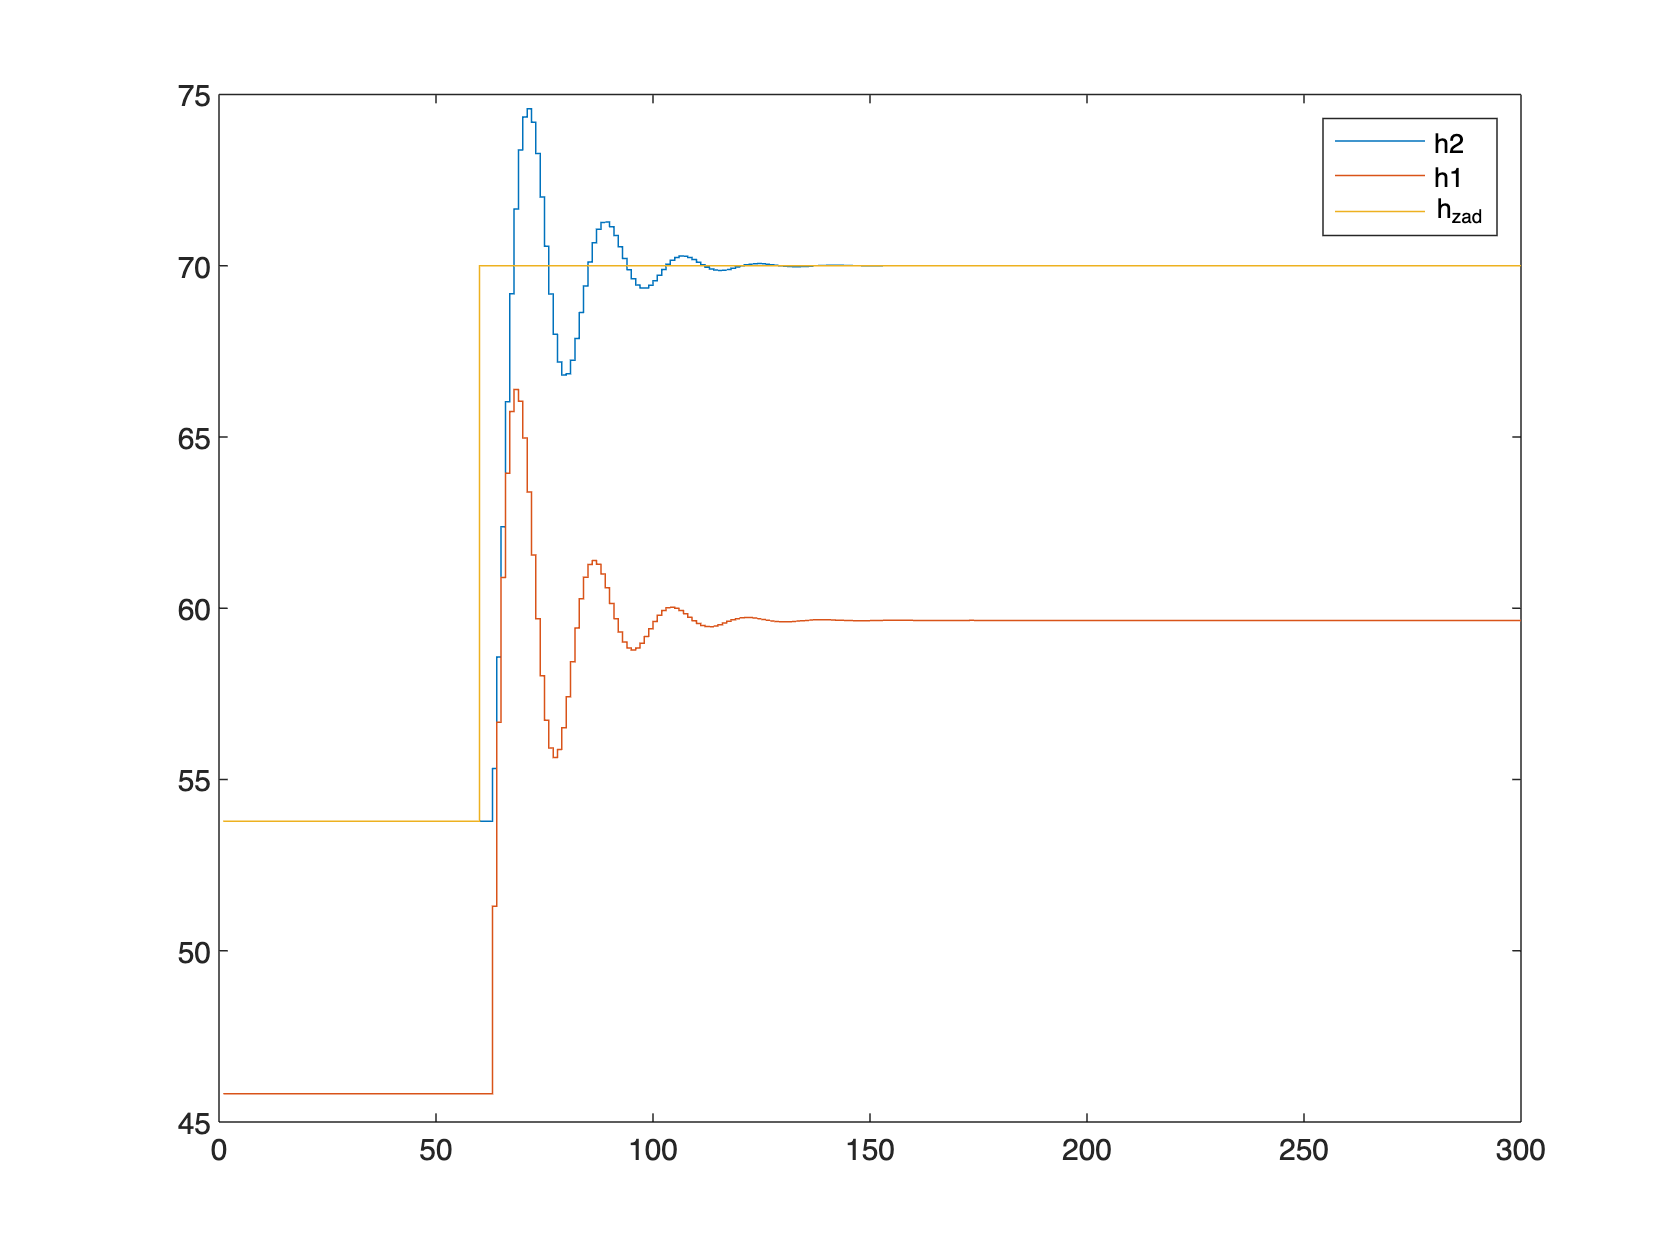

%Zadanie 1 - DMC
D = 50; N = 30; Nu = 5; lambda = 1; Ts = 40; t_span = 1:Ts;

tau = 120;
FD = @(t) 15;

kk =300; ks = 60;
Upp = 73;
h1_0 = 45.8225;            
h2_0 = 53.7778;

[M, Mp, K, ke, Ku] = offline_DMC(s, D, N, Nu, lambda);

h_zad(1:ks-1) = h2_0; h_zad(ks:kk) = 70; 

h1(1:ks-1) = h1_0;
h1(ks:kk) = 0;
h2(1:ks-1) = h2_0;
h2(ks:kk) = 0;
u(1:ks-1) = Upp;
u(ks:kk) = 0;
e(1:kk) = 0;
delta_u(1:kk) = 0;

% min_delta_u = -1.000000e-01;
% max_delta_u = 1.000000e-01;
% 
% min_u = 0.6;
% max_u = 1.2;

for k = ks:kk

    F1 = @(t) u(k - tau/Ts);
    [~, h] = zbiornik(t_span, h1_0, h2_0, F1, FD);

    h1(k) = h(end,1); 
    h2(k) = h(end,2);
    h1_0 = h1(k);
    h2_0 = h2(k);


    e(k) = h_zad(k) - h2(k);

    delta_sum = 0;
    for j = 1:D-1
        delta_sum = delta_sum + Ku(j)*delta_u(k-j);
    end

    delta_u(k) = ke*e(k) - delta_sum;
    % delta_u(k) = min(max(delta_u(k), min_delta_u), max_delta_u);

    u(k) = delta_u(k) + u(k-1);
    % u(k) = min(max(u(k), min_u), max_u);
end

figure;
stairs(h2);
hold on
stairs(h1);
stairs(h_zad);
legend('h2', 'h1','h_zad')
hold off

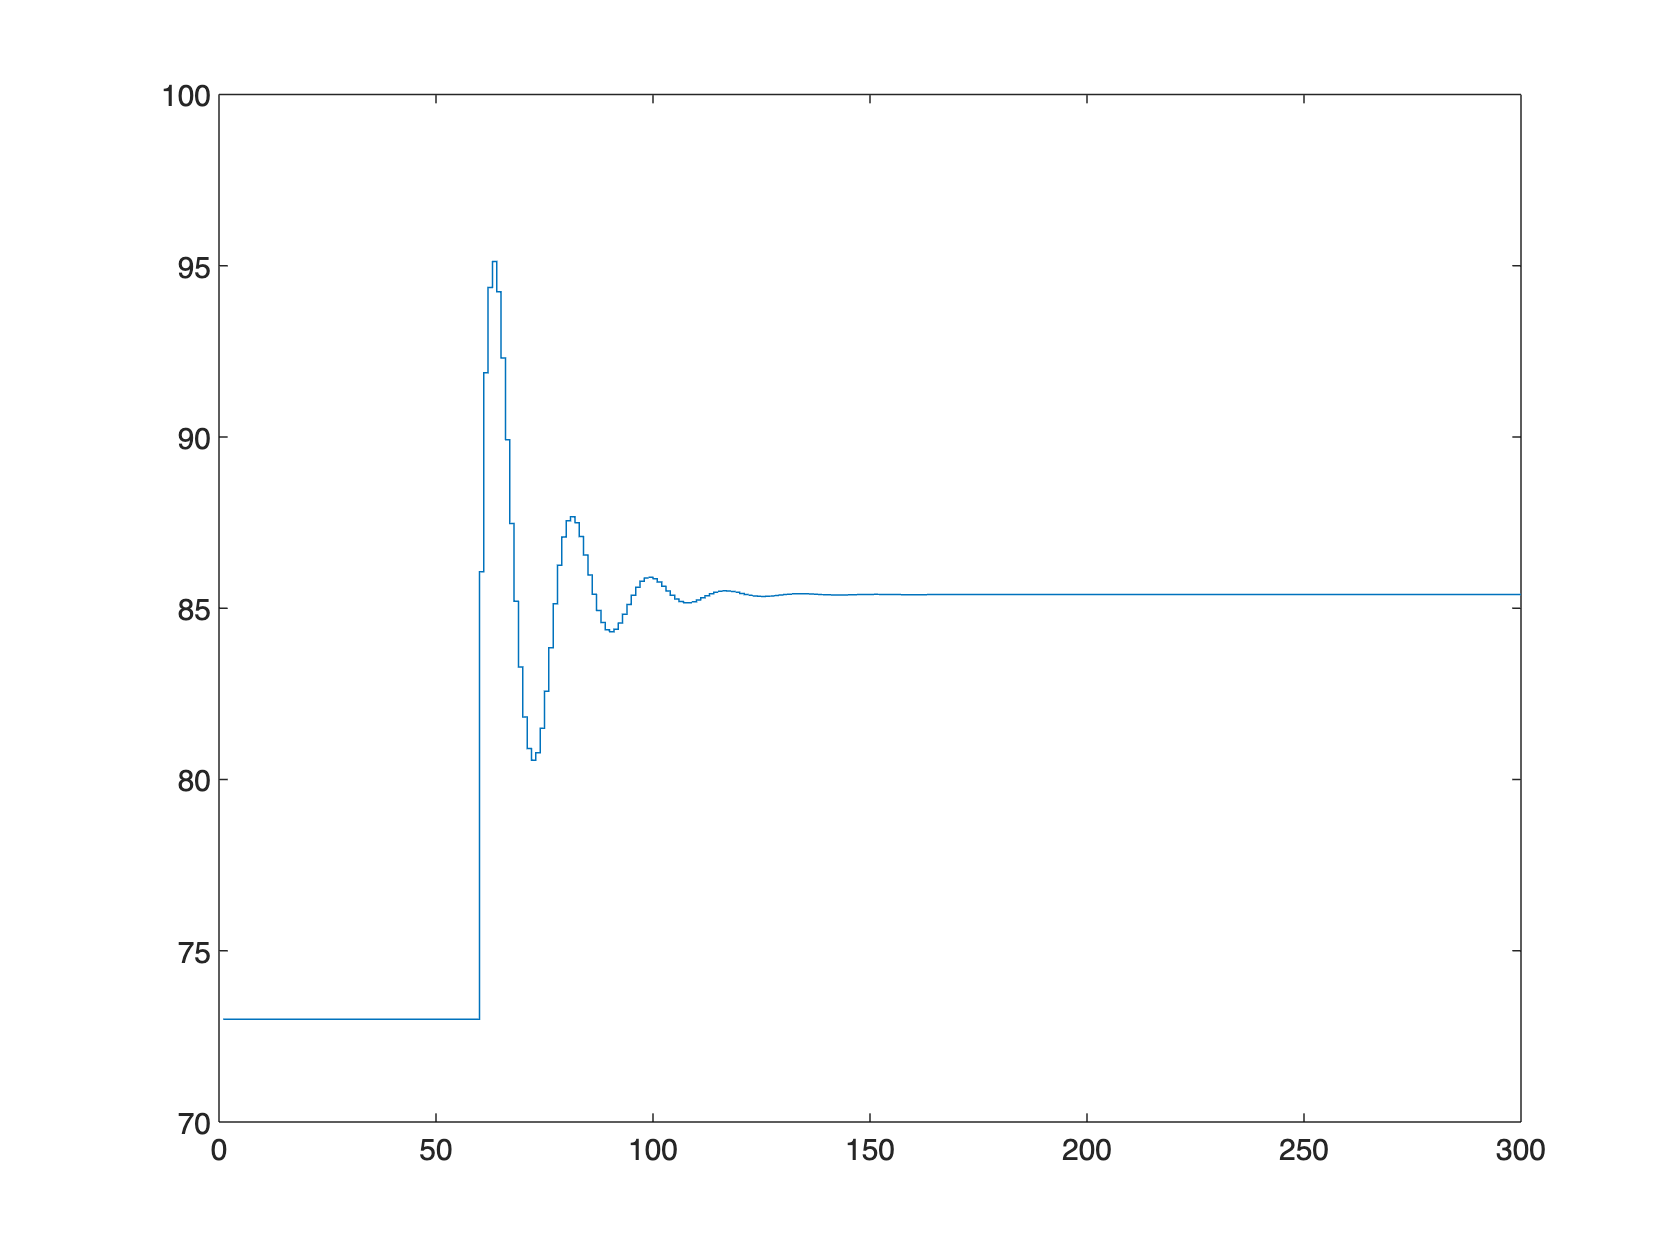

figure;
stairs(u);